 clc; clearvars; close all;
% Chuyển toàn bộ về tham chiếu toàn cục

## XÁC ĐỊNH CÁC TRỤC TỌA ĐỘ

% Toàn cục
% Hệ tọa độ toàn cục tại điểm [0,0,0] với trục z hướng lên
Global_Reference = [0, 0, 0];
Global_x = [1, 0, 0];
Global_y = [0, 1, 0];
Global_z = [0, 0, 1];

## User (Hệ tọa độ User tham chiếu đến hệ tọa độ toàn cục) 

User_Global_Position = [2, 2, 2] 

User_Global_Position =      2     2     2


% Hướng hiện tại của hệ tọa độ User trong hệ tọa độ toàn cục
User_Global_Rotation = [1, 0, 0, 0];
% Chuẩn hóa quaternions
User_Global_Rotation = quatnormalize(User_Global_Rotation) 

User_Global_Rotation =      1     0     0     0


User_x = quatrotate_(User_Global_Rotation, Global_x);
User_y = quatrotate_(User_Global_Rotation, Global_y);
User_z = quatrotate_(User_Global_Rotation, Global_z);

## Object

Hệ tọa độ vật thể tham chiếu đến hệ tọa độ User

%------------------------------Nhập vị trí bắt đầu của vật thể-------------------------------%
% Vị trí hiện tại của vật thể trong hệ tọa độ User   
Object_User_Position = [1, 1, 1]; 
% Hướng hiện tại của vật thể trong hệ tọa độ User
Object_User_Rotation = [1, 0, 0, 0]; 
%____________________________________________________________________________________________%

% Chuẩn hóa quaternions
Object_User_Rotation = quatnormalize(Object_User_Rotation); 
% Hệ tọa độ vật thể tham chiếu đến hệ tọa độ toàn cục
% Vị trí hiện tại của vật thể về hệ tọa độ toàn cục
Object_Global_Position = User_Global_Position + quatrotate_(User_Global_Rotation, Object_User_Position) 

Object_Global_Position =      3     3     3


% Hướng hiện tại của vật thể về hệ tọa độ toàn cục
Object_Global_Rotation = quatmultiply(Object_User_Rotation, User_Global_Rotation)

Object_Global_Rotation =      1     0     0     0



% Object_x = quatrotate_(Object_User_Rotation, User_x);
% Object_y = quatrotate_(Object_User_Rotation, User_y);
% Object_z = quatrotate_(Object_User_Rotation, User_z);
Object_x = quatrotate_(Object_Global_Rotation, Global_x);
Object_y = quatrotate_(Object_Global_Rotation, Global_y);
Object_z = quatrotate_(Object_Global_Rotation, Global_z);

## Vẽ các hệ tọa độ

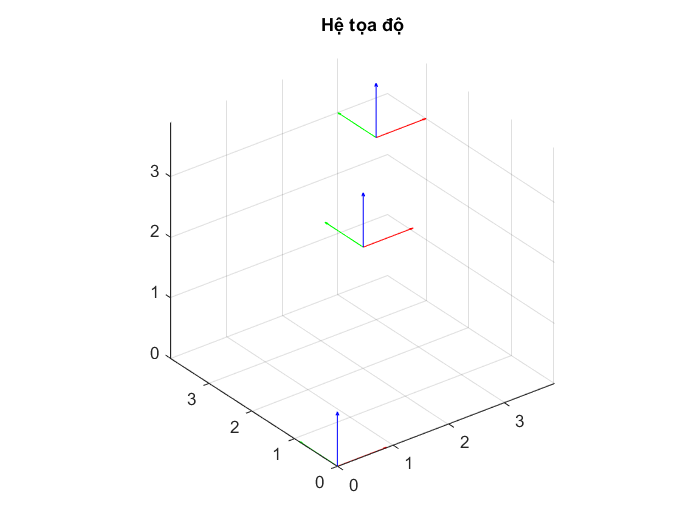

figure;
hold on;
quiver3(Global_Reference(1), Global_Reference(2), Global_Reference(3), Global_x(1), Global_x(2), Global_x(3), 'r');
quiver3(Global_Reference(1), Global_Reference(2), Global_Reference(3), Global_y(1), Global_y(2), Global_y(3), 'g');
quiver3(Global_Reference(1), Global_Reference(2), Global_Reference(3), Global_z(1), Global_z(2), Global_z(3), 'b');

quiver3(User_Global_Position(1), User_Global_Position(2), User_Global_Position(3), User_x(1), User_x(2), User_x(3), 'r');
quiver3(User_Global_Position(1), User_Global_Position(2), User_Global_Position(3), User_y(1), User_y(2), User_y(3), 'g');
quiver3(User_Global_Position(1), User_Global_Position(2), User_Global_Position(3), User_z(1), User_z(2), User_z(3), 'b');

quiver3(Object_Global_Position(1), Object_Global_Position(2), Object_Global_Position(3), Object_x(1), Object_x(2), Object_x(3), 'r');
quiver3(Object_Global_Position(1), Object_Global_Position(2), Object_Global_Position(3), Object_y(1), Object_y(2), Object_y(3), 'g');
quiver3(Object_Global_Position(1), Object_Global_Position(2), Object_Global_Position(3), Object_z(1), Object_z(2), Object_z(3), 'b');

% % Đặt các giới hạn trục tọa độ
% xlim([-20, 20]);
% ylim([-20, 20]);
% zlim([-20, 20]);

% Hiển thị dưới dạng xem 3D
view(3);
axis equal; 
grid on;

% Đặt tên cho biểu đồ
title('Hệ tọa độ');

## QUY HOẠCH CHUYỂN ĐỘNG

Vị trí hiện tại của vật thể tham chiếu về hệ trục tạo độ toàn cục

p_init = Object_Global_Position

p_init =      3     3     3


q_init = Object_Global_Rotation

q_init =      1     0     0     0



%---------------------------Nhập vị trí đến------------------------%
    % Vị trí đích đến của vật thể tham chiếu về hệ trục tọa độ gốc
    p_end  = [5, 5, -5];
    q_end  = [0.7071, 0, 0, 0.7071];    
%__________________________________________________________________%

% Vị trí đích đến của vật thể tham chiếu về hệ trục tọa độ toàn cục
q_end = quatnormalize(q_end); % Chuẩn hóa quaternions
Object_Global_Position_Target = User_Global_Position + quatrotate_(User_Global_Rotation, p_end);
Object_Global_Rotation_Target = quatmultiply(q_end, User_Global_Rotation);
p_Target  = Object_Global_Position_Target

p_Target =      7     7    -3


q_Target  = Object_Global_Rotation_Target

q_Target =     0.7071         0         0    0.7071


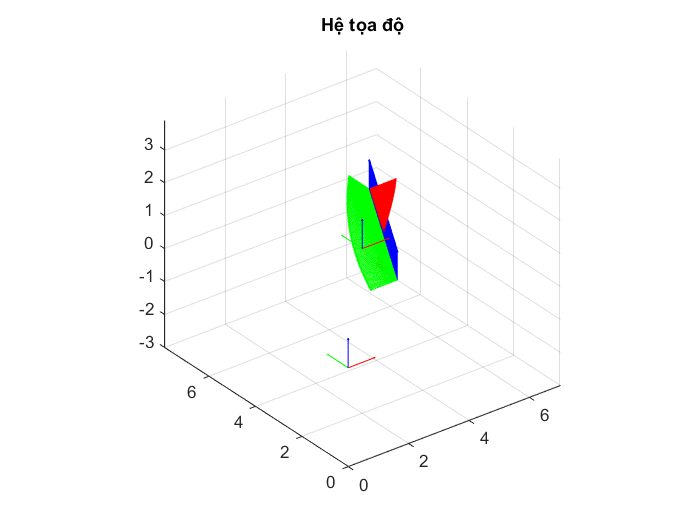


%---------------------------Nhập thông số------------------------%
    % Thông số quá trình di chuyển
    t_s = 0.02; % Thời gian giữa các bước
    t_total = 02; % Thời gian hoàn thành 
%________________________________________________________________%

num_steps = t_total / t_s; % Số lượng bước nhỏ
t_step = linspace(0, t_total, num_steps+1); % Mảng thời gian nhỏ

% Tính toán quaternion tương ứng với mỗi bước thời gian nhỏ
for i = 1:num_steps+1
    t_current = t_step(i);
    t = t_current/t_total;

    % Tính toán vị trí tương ứng với thời gian hiện tại
    % Sử dụng thuật toán nội suy giữa p_init và p_Target
    p_interpolated = (1-t) * p_init + t * p_Target;
    Object_Global_Position = p_interpolated;

    % Tính toán quaternion tương ứng với thời gian hiện tại
    % Sử dụng thuật toán Slerp nội suy giữa q_init và q_Target
    q_interpolated = slerp(q_init, q_Target, t , 0);

    % Xoay vector x,y,z
    Object_x = quatrotate_(q_interpolated, Global_x);
    Object_y = quatrotate_(q_interpolated, Global_y);
    Object_z = quatrotate_(q_interpolated, Global_z);
    % Vẽ vector x,y,z
    quiver3(Object_Global_Position(1), Object_Global_Position(2), Object_Global_Position(3), Object_x(1), Object_x(2), Object_x(3), 'r');
    quiver3(Object_Global_Position(1), Object_Global_Position(2), Object_Global_Position(3), Object_y(1), Object_y(2), Object_y(3), 'g');
    quiver3(Object_Global_Position(1), Object_Global_Position(2), Object_Global_Position(3), Object_z(1), Object_z(2), Object_z(3), 'b');

end